# BarTrace

Application to track the path and speed of a barbell when weightlifting. 

Started by Dave Bergstein (dbergstein@gmail.com)

## Issues

- add tests

- Fix detect by imagine processing

- Check training

- carrying around video data and video object in liftVid is unecessary

## Project Organization

- application: production code including production model

- data: raw data, see readme files for credit & permission

- models: image processing and trained models

- training: code for training models

- exploring: area to play around

- tests: unit, performance, and application tests (to be written)

## Getting Started

Import video

vid = liftVid("DaveShort.mp4");

Find plate and draw in circle

vid.tracePlate("modelC");

starting


vid.annotate;

annotating video


Show result

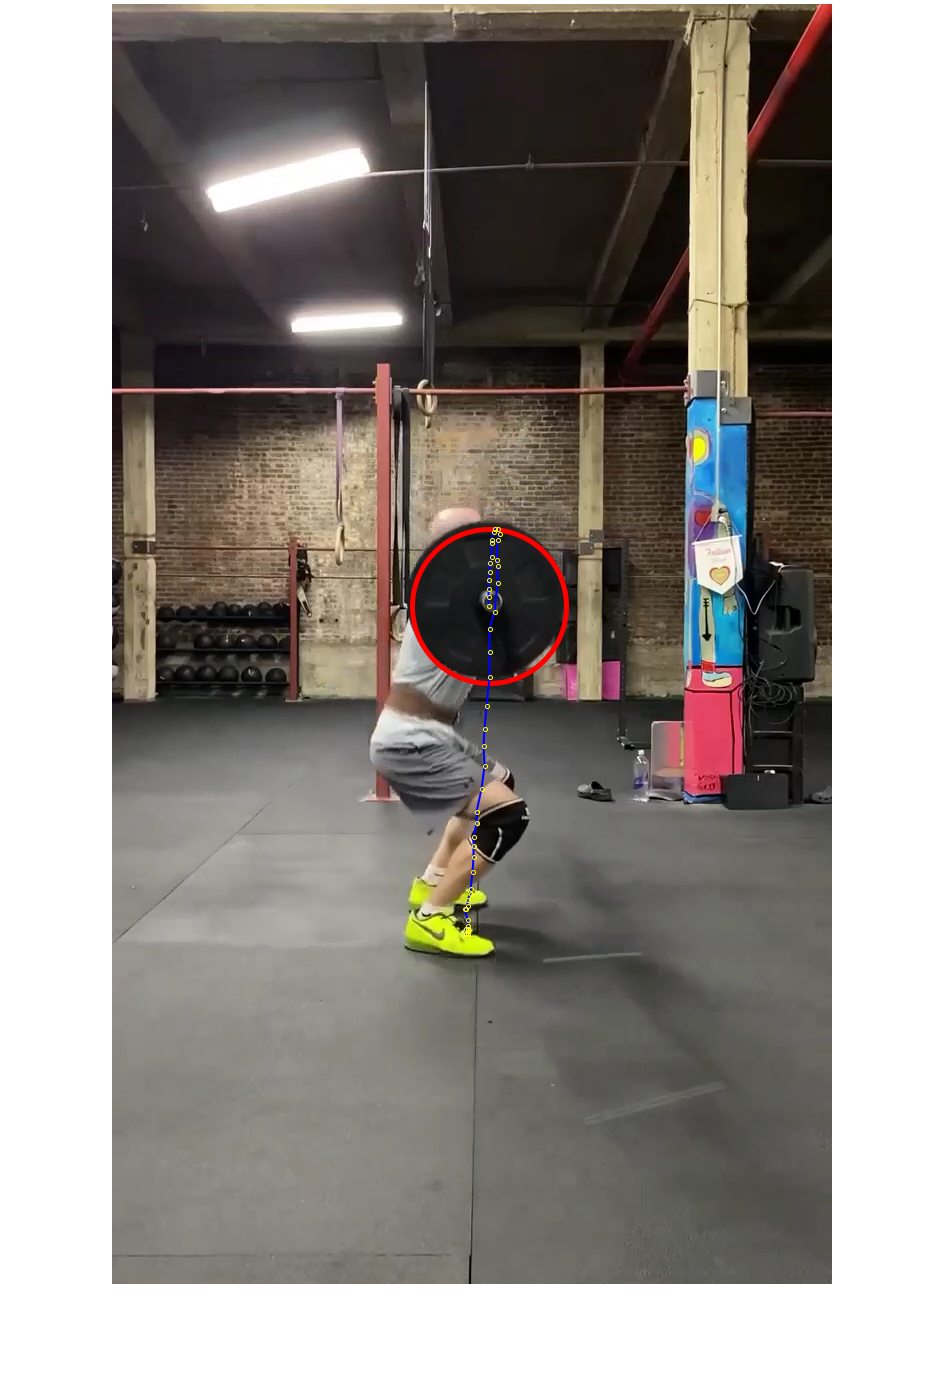

imshow(vid.vid(55).cdata)

%vid.play;  %play video

Save annotated video

%vid.save("Result1");

## Analyze the second pull

edit("Analyze2ndPull.mlx")

## Details

liftVid finds the barbell plate in each frame and traces it's path. Yellow markers at each frame help gauge barbell speed. Videos were all shot on an iPhone 11 at 30 fps. The model was only trained with black plates on a red and black background.

I used two approaches to find the plate in each frame:

- Image processing based on imfindcircles

- Deep learning based on a pre-trained CNN network with a YOLO network on the back end trained here

Image processing (approach #1) was first used to label images. The image processing took long and wasn't always accurate, especially when the black plates were against a black background. The labeling was adjusted and improved using the Video Labeling App. Training data with different lifters was used to train the model.